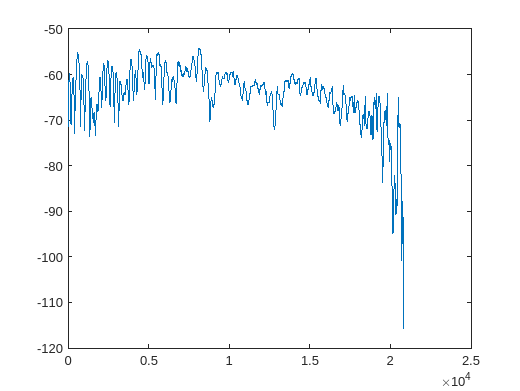

clear 
clc

steerAng = 35;
fs = 41.667e3;
sweepDur = 10;
silenceDur = 2;
tone = sweeptone(sweepDur, silenceDur, fs, 'SweepFrequencyRange', [20 20.8e3]);
tone = [zeros(silenceDur*fs-1, 1); tone];
t = 0:1/fs:sweepDur+(silenceDur-1/fs)*2;

maxDegs = 179;
outputPower = zeros(maxDegs+1, 4096);
outputFreq = zeros(maxDegs+1, 4096);

% Open a parallel pool if not already open
if isempty(gcp('nocreate'))
    parpool('local'); % Adjust number of workers as needed
end

parfor d = 0:maxDegs
    % Construct the file name for each degree
    fileName = sprintf('degree_%d', d);
    fileID = fopen(fileName);
    
    if fileID == -1
        error('Failed to open file: %s', fileName);
    end
    
    data = fread(fileID, 'single'); 
    fclose(fileID);
    
    data = data / (power(2, 31) - 1);
    numMics = 8;
    numSamples = 190;
    onePacketLength = numSamples * numMics;
    numPacketsInData = floor(length(data) / onePacketLength);
    splitdata = zeros(numSamples * numPacketsInData, numMics);
    
    for i = 0:numPacketsInData-1
        for m = 1:numMics
            micStartIdx = 1 + (m-1)*numSamples + i*onePacketLength;
            micEndIdx = m*numSamples + i*onePacketLength;
            splitdata(i*numSamples + 1:(i+1)*numSamples, m) = data(micStartIdx:micEndIdx);
        end
    end
    
    splitdata = splitdata';
    impulse = impzest(tone, splitdata(8, :)');
    impulse = impulse / max(abs(impulse));
    
    [p, f] = pspectrum(impulse, fs);
    
    outputPower(d + 1, :) = p;
    outputFreq(d + 1, :) = f;
end

outputPower = flip(outputPower);
outputdB = 10 * log10(outputPower);
outputdB = outputdB - max(10 * log10(outputPower));
plot(outputFreq(3, :), 10 * log10(outputPower(3, :)));

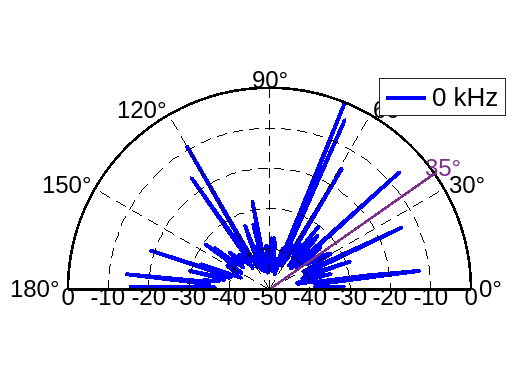

circPlot(outputFreq(20, :), (0:maxDegs) * pi / 180, outputdB', steerAng);

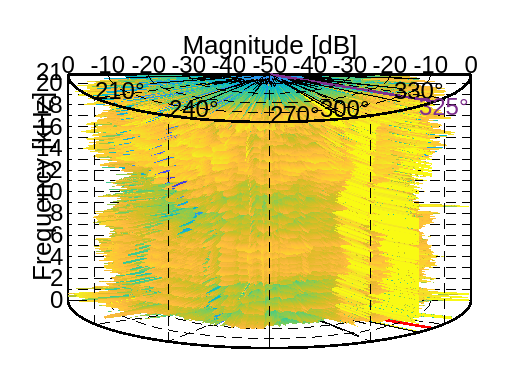

cylindricalPlot(outputFreq(1, :), (0:maxDegs) * pi / 180, outputdB', steerAng, [180, 10]);


% Close the parallel pool (optional)
delete(gcp('nocreate'));

Parallel pool using the 'Processes' profile is shutting down.
